x1 = [1, 2, 3, 4];
x2 = [5, 6, 7, 8];
n1 = length(x1);
n2 = length(x2);
N = max(n1, n2);

if(n2>n1)
    x4 = [x1, zeros(1,N-n1)];
    x5 = x2;
elseif(n2==n1)
    x4 = x1;
    x5 = x2;
else
    x4 = x1;
    x5 = [x2, zeros(1, N-n2)];
end
x3 = zeros(1,N);
x6 = zeros(N,N);
for m=0:N-1
    x3(m+1)=0;
    for n=0:N-1
        j = mod(m-n, N);
        x6(m+1,n+1) = x5(j+1);
        x3(m+1) = x3(m+1) + x4(n+1).*x5(j+1);
    end
end
x3

x3 =     66    68    66    60


x6

x6 =      5     8     7     6
     6     5     8     7
     7     6     5     8
     8     7     6     5


subplot(4,1,1)
stem(abs(x3))
title('Circular Convolution using formula')

x = [1, 2, 3, 4];
y = [5, 6, 7, 8];
dftX = zeros(1,N);
dftY = zeros(1,N);
for k = 0:N-1
    for n = 0:N-1
        dftX(k+1) = dftX(k+1)+ (x(n+1) * exp(-1j*2*pi*(n)*(k)/N)); 
        dftY(k+1) = dftY(k+1)+ (y(n+1) * exp(-1j*2*pi*(n)*(k)/N)); 
    end
end
dftConv = dftX.*dftY;
res = ifft(dftConv)

res =   66.0000 + 0.0000i  68.0000 + 0.0000i  66.0000 + 0.0000i  60.0000 - 0.0000i


subplot(4,1,2)
stem(abs(res))
title('Circular convolution using DFT(freq domain)')

y = cconv(x1,x2,N)

y =     66    68    66    60


subplot(4,1,3)
stem(abs(y))
title('Circular Convolution using inbuilt function')

d = y - x3

d =      0     0     0     0


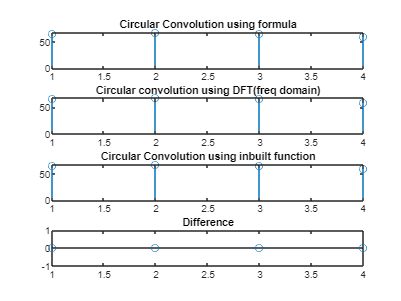

subplot(4,1,4)
stem(round(d))
title('Difference')